# Add Figure Snapshot to Presentation

To add an image of a MATLAB figure to a presentation, this example prints the figure to an image file, creates an `mlreportgen.ppt.Picture` object from the file, and adds the `Picture` object to a slide in the presentation.

Create a presentation.

import mlreportgen.ppt.*

ppt = Presentation("myFigurePresentation.pptx");
open(ppt);

 Add a slide to the presentation.

slide = add(ppt,"Title and Content");

Add a title to the slide.

replace(slide,"Title","surf(peaks)");

Create a MATLAB figure with a surface plot.

fig = figure;
surf(peaks);

Print the figure to an image file. Do not delete the image file before generating the presentation.

figSnapshotImage = "figSnapshot.png";
print(fig,"-dpng",figSnapshotImage);

Create an `mlreportgen.ppt.Picture` object using the image file.

figPicture = Picture(figSnapshotImage);

Add the `Picture` object to the slide.

replace(slide,"Content",figPicture);

Close the presentation.

close(ppt);

Delete the figure and the image file. 

delete(fig);
delete(figSnapshotImage);

View the presentation.

rptview(ppt);

Here is the generated slide with the image of the figure:

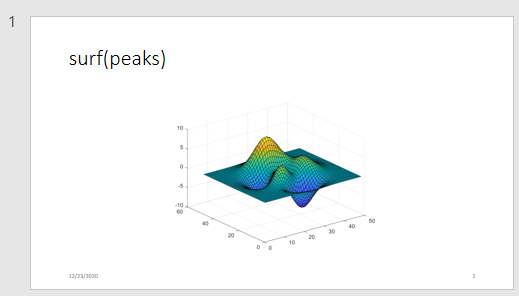

*Copyright 2020 The MathWorks, Inc.*